clc; clear all;
robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column');

Loading **KukaIiwa7** Robot

numJoints = numel(homeConfiguration(robot));
endEffector = 'iiwa_link_ee_kuka';
helperCreateObstaclesKINOVA;

taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = findCollisionFreeIK(robot, world, endEffector, taskInit);

taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal'];

finalRobotJConfig   = findCollisionFreeIK(robot, world, endEffector, taskFinal);

assert(~checkCollision(robot,currentRobotJConfig,world,"IgnoreSelfCollision","on"))
assert(~checkCollision(robot,finalRobotJConfig,   world,"IgnoreSelfCollision","on"))

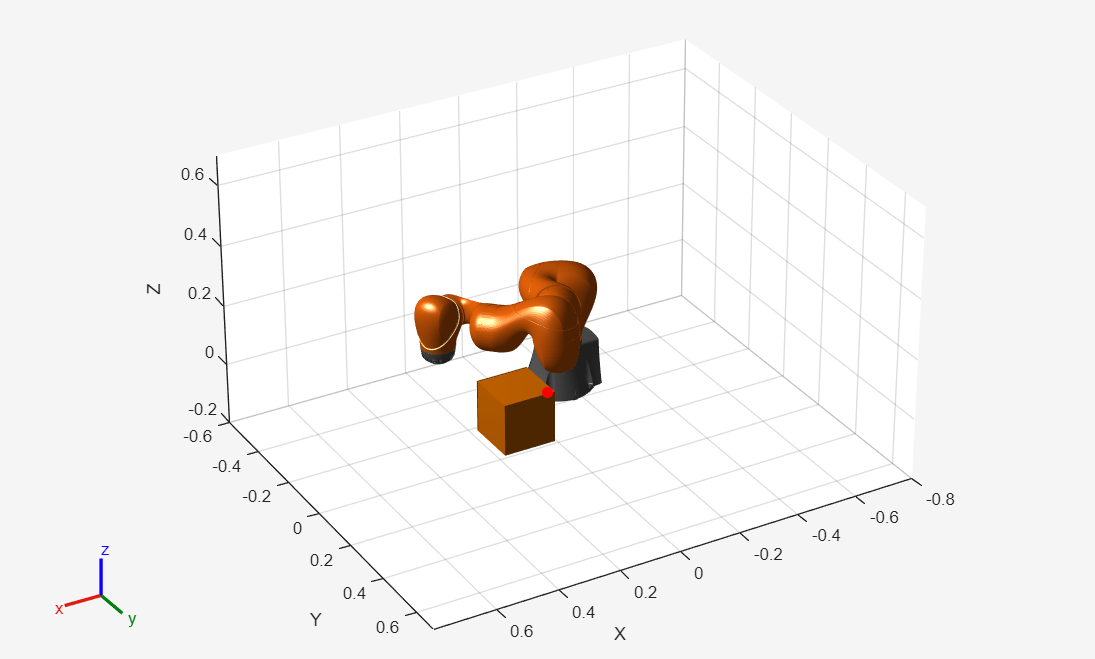

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

safetyDistance = 0.01; 

Elapsed time is 1.897163 seconds.


Qtheta = 64.0603

RAR = 64.0603

Previous Qθ = 64.060186 | New Qθ = 64.060307 | ΔQ = 0.000121
STOMP Finished.


isTrajectoryInCollision = logical
   0


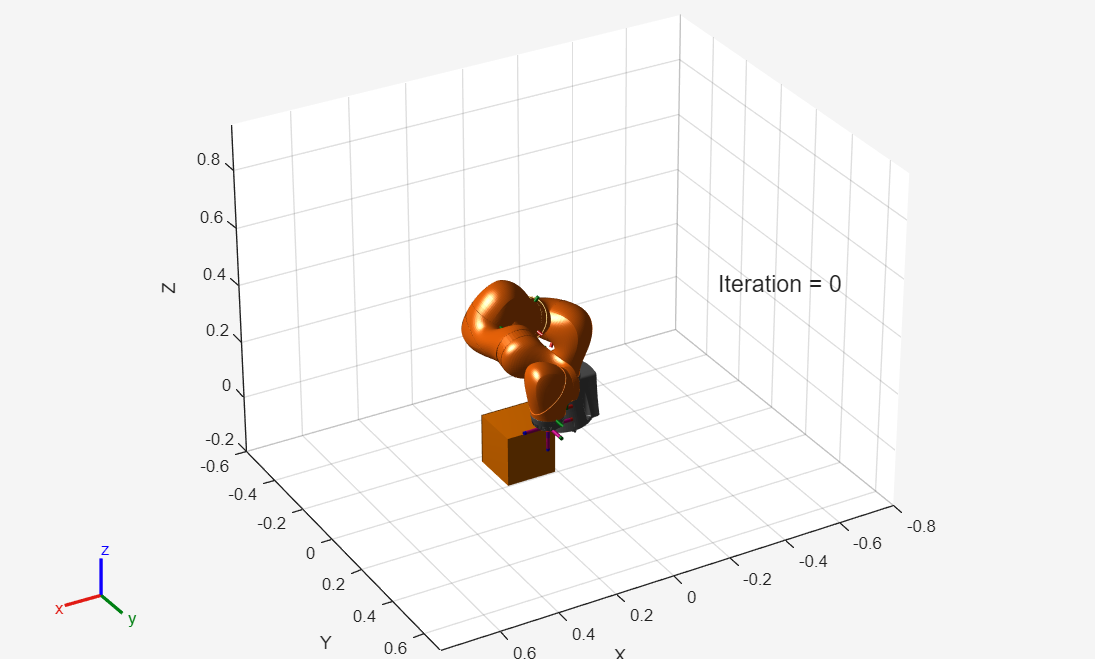

enableVideoTraining = 1;
enableVideo = 1;
helperSTOMP;